t = Cartposition(:,1);
dt = t(2)-t(1);
y = Cartposition(:,2);
ydot = diff(y)/dt; ydot(end+1) = ydot(end);

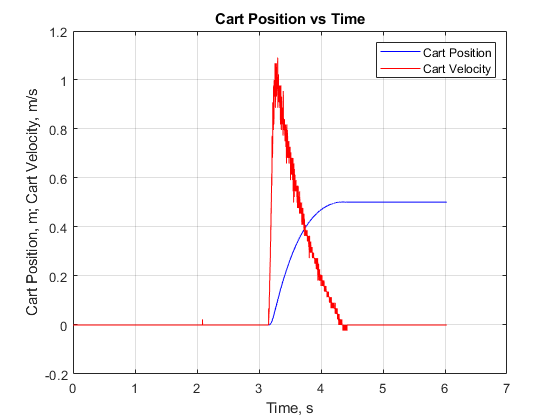

figure(1)
plot(t,y,'b')
title("Cart Position vs Time")
xlabel("Time, s")
ylabel("Cart Position, m; Cart Velocity, m/s")
grid on
hold on
plot(t,ydot,'r')
legend("Cart Position","Cart Velocity")

m = 0.94; gamma = 1.7235; Bemf = 7.7236;
ydot_avg = mean(ydot(3593:3747))

ydot_avg = 0.4802

y_inf = y(end);
Beq = (y_inf/(ydot_avg*m))^-1

Beq = 0.8998

c = Bemf + Beq

c = 8.6234